%% 天线实验数据处理脚本
% 对应任务：读取S参数，绘制幅度(dB)曲线，计算并绘制输入阻抗曲线
% 需要工具箱：RF Toolbox (通常包含在标准工程版MATLAB中)

clear; clc; close all;

%% 1. 导入数据
disp('请选择你的 .s1p 文件...');

请选择你的 .s1p 文件...


[file, path] = uigetfile('*.s1p', '选择网络分析仪保存的S1p文件');

if isequal(file, 0)
    disp('用户取消了文件选择');
    return;
end

fullPath = fullfile(path, file);

% 使用 rfparam 和 sparameters 读取 Touchstone 文件
try
    % 创建 S参数对象
    s_object = sparameters(fullPath);
    
    % 提取频率 (转换为 GHz 方便绘图)
    freq = s_object.Frequencies; 
    freq_GHz = freq / 1e9; 
    
    % 提取 S11 参数 (复数数据)
    % squeeze 用于去除多余的维度，确保得到一个列向量
    s11_complex = squeeze(s_object.Parameters(1,1,:));
    
    % 获取特性阻抗 (通常为 50 欧姆)
    Z0 = s_object.Impedance;
    
catch ME
    error('读取文件失败。请确保安装了 RF Toolbox，并且文件格式正确。错误信息: %s', ME.message);
end

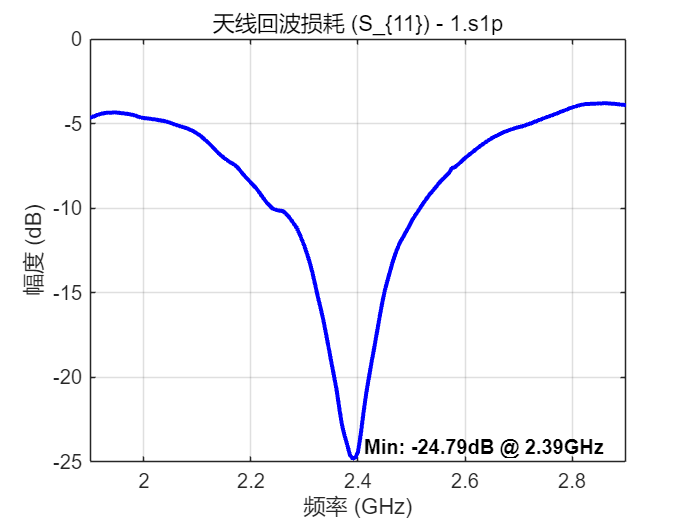


%% 2. 任务二：绘制 S 参数幅度曲线 (dB)
% 公式: S11(dB) = 20 * log10(|S11|)

s11_mag_dB = 20 * log10(abs(s11_complex));

figure('Name', 'S参数幅度曲线', 'Color', 'w');
plot(freq_GHz, s11_mag_dB, 'LineWidth', 2, 'Color', 'b');
grid on;
title(['天线回波损耗 (S_{11}) - ' file], 'Interpreter', 'none');
xlabel('频率 (GHz)');
ylabel('幅度 (dB)');
xlim([1.9 2.9]); % 锁定题目要求的频率范围
% 添加一个标记显示最小值 (谐振点)
[min_val, min_idx] = min(s11_mag_dB);
text(freq_GHz(min_idx), min_val, sprintf('  Min: %.2fdB @ %.2fGHz', min_val, freq_GHz(min_idx)), ...
    'VerticalAlignment', 'bottom', 'FontWeight', 'bold');

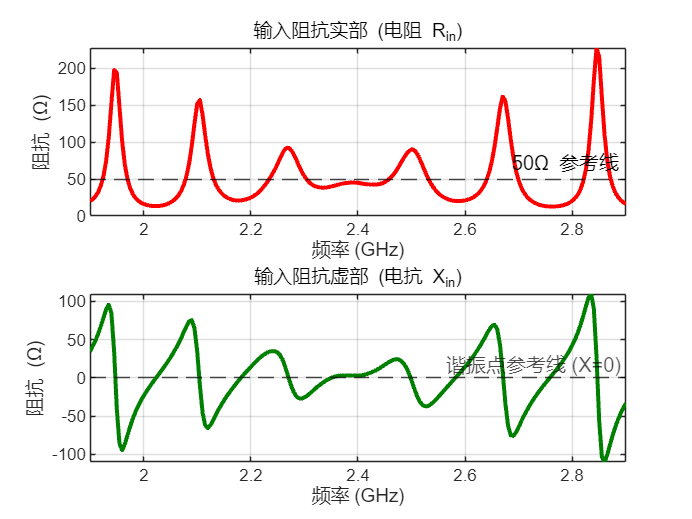


%% 3. 任务三：计算并绘制输入阻抗 (实部与虚部)
% 传输线理论公式: Zin = Z0 * (1 + S11) / (1 - S11)
% 注意：这里的计算必须使用复数形式的 S11

Z_in = Z0 .* (1 + s11_complex) ./ (1 - s11_complex);

% 提取实部 (电阻) 和 虚部 (电抗)
R_in = real(Z_in);
X_in = imag(Z_in);

figure('Name', '天线输入阻抗特性', 'Color', 'w');

% 绘制实部
subplot(2,1,1);
plot(freq_GHz, R_in, 'LineWidth', 2, 'Color', 'r');
grid on;
title('输入阻抗实部 (电阻 R_{in})');
xlabel('频率 (GHz)');
ylabel('阻抗 (\Omega)');
xlim([1.9 2.9]);
yline(50, '--k', '50\Omega 参考线'); % 绘制50欧姆参考线

% 绘制虚部
subplot(2,1,2);
plot(freq_GHz, X_in, 'LineWidth', 2, 'Color', [0 0.5 0]); % 深绿色
grid on;
title('输入阻抗虚部 (电抗 X_{in})');
xlabel('频率 (GHz)');
ylabel('阻抗 (\Omega)');
xlim([1.9 2.9]);
yline(0, '--k', '谐振点参考线 (X=0)'); % 绘制0欧姆参考线


disp('处理完成！已生成两张图表。');

处理完成！已生成两张图表。
